Standard design criteria:         

Overshoot less than 10%                               Steady-state error less than 2% seconds

Settling time less than 10 seconds                 Rise time less than 2

Transfer function of Pitch (P) for input elevator Deflection (D) in frequency domain:

% Open-loop response
s = tf('s');
P_pitch = (1.151*s+0.1774)/(s^3+0.739*s^2+0.921*s);

Open-loop response does not meet design criteria:

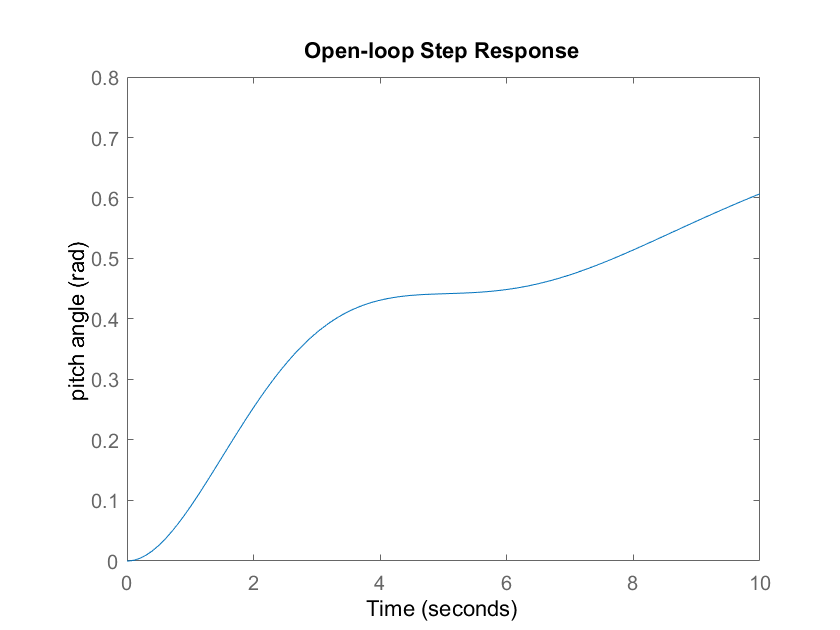

t = [0:0.01:10];
step(0.2*P_pitch,t);
axis([0 10 0 0.8]);
ylabel('pitch angle (rad)');
title('Open-loop Step Response');

To generate the state-space model of he given system, use the following spacial vectors:

A = [-0.313 56.7 0; -0.0139 -0.426 0; 0 56.7 0];
B = [0.232; 0.0203; 0];
C = [0 0 1];
D = [0];
pitch_ss = ss(A,B,C,D)

pitch_ss =
 
  A = 
            x1       x2       x3
   x1   -0.313     56.7        0
   x2  -0.0139   -0.426        0
   x3        0     56.7        0
 
  B = 
           u1
   x1   0.232
   x2  0.0203
   x3       0
 
  C = 
       x1  x2  x3
   y1   0   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



Find poles and zeros to drive steady-state error to minimum. The system is bounded by controller to get closed-loop transfer function.

% CLTF
pole(P_pitch)

ans =    0.0000 + 0.0000i
  -0.3695 + 0.8857i
  -0.3695 - 0.8857i


sys_cl = feedback(P_pitch,1)

sys_cl =
 
           1.151 s + 0.1774
  ----------------------------------
  s^3 + 0.739 s^2 + 2.072 s + 0.1774
 
Continuous-time transfer function.



step(0.2*sys_cl);
ylabel('pitch angle (rad)');
title('Closed-loop Step Response');

Examining the above closed-loop step response, the addition of feedback  has stabilized the system. In fact, the steady-state error appears to be driven to zero and there is no overshoot in the response, though the rise-time and settle-time requirements are not met.

poles = pole(sys_cl)

poles =   -0.3255 + 1.3816i
  -0.3255 - 1.3816i
  -0.0881 + 0.0000i


zeros = zero(sys_cl)

zeros = -0.1541

The character of the resulting step response is indicated by the location of the poles and zeros of the system's transfer function, in a similar manner to the way the system's stability properties were.

R = 0.2/s;
Y = zpk(sys_cl*R)

Y =
 
            0.2302 (s+0.1541)
  -------------------------------------
  s (s+0.08805) (s^2 + 0.6509s + 2.015)
 
Continuous-time zero/pole/gain model.



[r,p,k] = residue(0.2*[1.151 0.1774],[1 0.739 2.072 0.1774 0])

r =   -0.0560 + 0.0160i
  -0.0560 - 0.0160i
  -0.0879 + 0.0000i
   0.2000 + 0.0000i


p =   -0.3255 + 1.3816i
  -0.3255 - 1.3816i
  -0.0881 + 0.0000i
   0.0000 + 0.0000i



k =

     []



The above results demonstrate that the closed-loop transfer function is  third order with a zero. Most of the relationships that we are familiar with for predicting the character of a  system's step response assume a standard underdamped second-order system with no zeros. Therefore, we cannot rely on these  relationships for this system. We can, however, transform the output back to the time domain to generate a time function for the  system's response to get some insight into how the poles and zeros of the closed-loop transfer function affect the system's  response.

% Nature of poles and zeros
[num,den] = residue(r(1:2),p(1:2),k);
tf(num,den)

ans =
 
   -0.1121 s - 0.08071
  ----------------------
  s^2 + 0.6509 s + 2.015
 
Continuous-time transfer function.



t = [0:0.1:70];
y = 0.2 - 0.0881*exp(-0.08805*t) - exp(-0.3255*t).*(0.1121*cos(1.3816*t)+0.0320*sin(1.3816*t));

The above plot again demonstrates that this closed-loop system does not meet the given design requirements. 

PROPORTIONAL CONTROL:

Addition of gain Kp = C(s) and using root locus, Bode plot to analyze the system.

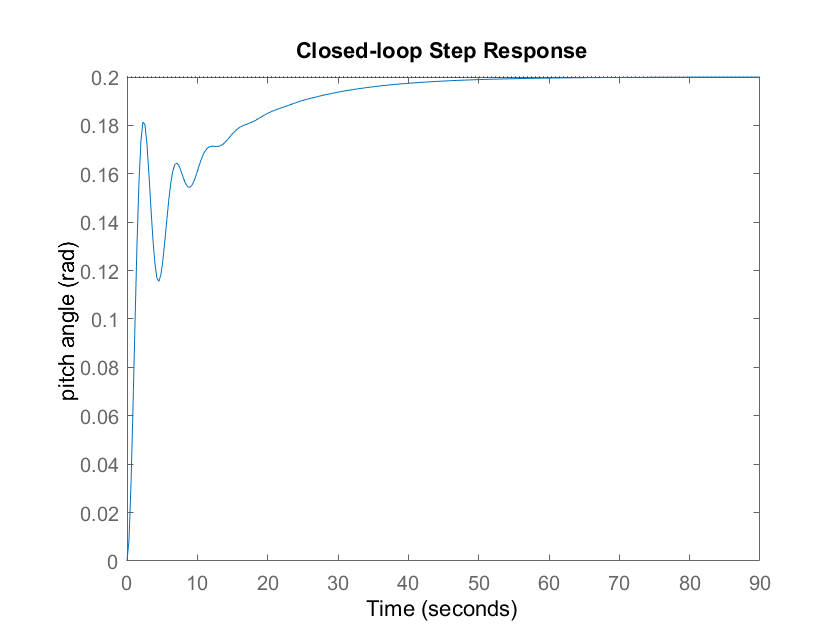

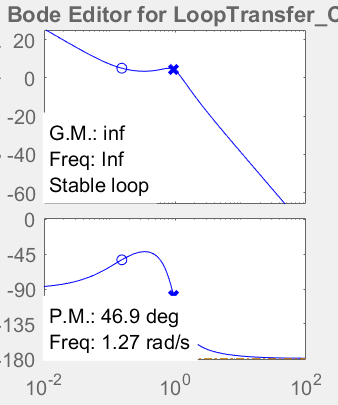

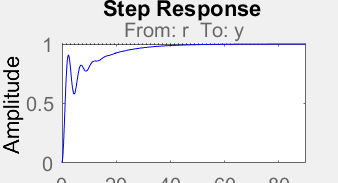

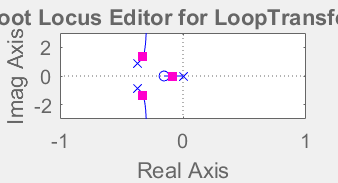

controlSystemDesigner(P_pitch)

% PID transfer function
Kp = 1;
Ki = 1;
Kd = 1;

s = tf('s');
C = Kp + Ki/s + Kd*s

C =
 
  s^2 + s + 1
  -----------
       s
 
Continuous-time transfer function.



Finaly tuning done using inbuilt MATLAB compensator toolbox.

This transfer function is a PID compensator with  = 0.5241,  = 1.0482, and  = 0.5241. The resulting closed-loop step response is in "PID_fully_tuned" image.

This response meets all of the given requirements as summarized below:    

Overshoot = 7.5% < 10%                                              Steady-state error = 0% < 2%

Settling time = 9.25 seconds < 10 seconds                  Rise time = 0.413 seconds < 2 seconds

Therefore, this PID controller will provide the desired performance of the aircraft's pitch.